##                                         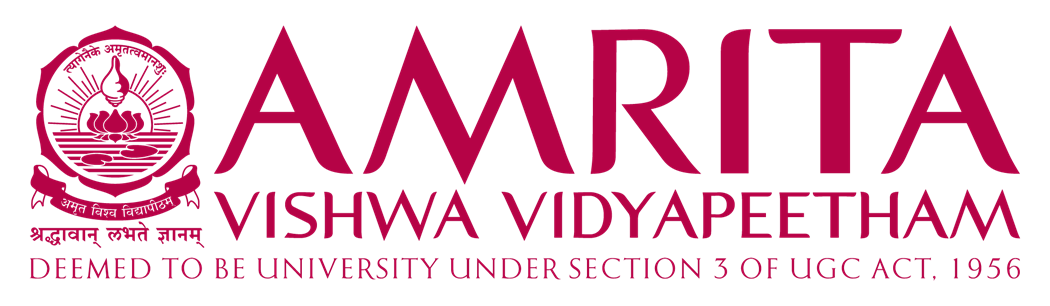

#   **22MAT220  -   Mathematics for Computing 3**

## **Reconstruction and Denoising of the EEG Signals using ADMM**

**Group-D14**

**Team Members**, 

Ravishanmugam K          - CB.SC.U4AIE24347

     Sharvesh Sivaganam       - CB.SC.U4AIE24355

Vignes V M                      - CB.SC.U4AIE24359

Sri Harini MP                   - CB.SC.U4AIE24358

#            PART-1:Reconstruction of the EEG Signals

Human brain generated weak signals called Electroencephalography (EEG) is measured by the Neurocom EEG 23-channel system ,which is stored in the European Data Format(edf), is used to calcualte the several brain related information ,it can resemble several solutions to the existing problems.It is capable of revealing the emotion and movement controlled by the brain.Around 23 channels contain the information about the signals generated by the brain.Considering an sample of the signals under the compresses sensing concept ,we will reconstruct the signal from the sample(say 25% for this case)

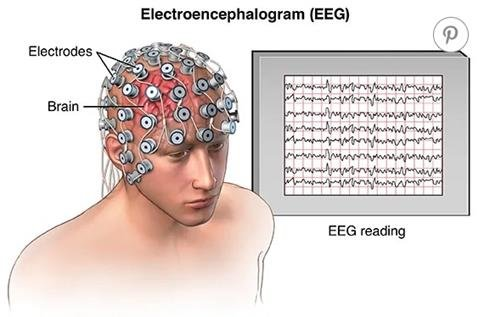

## Dataset Description:

There are totally about 36 subjects(individuals) for the performing the eeg signals , where for each subject is considering the catregory of before and after performing the arithmetic task.Where all the 36 subjects from the 36 were named as subjectxx_1 is signals recored before the performing the airthmetic task and subjectxx_2 is after the arithmetic task.24 subjects were considered to be good quality count(mean number of operation in 4 minutes is 21,SD = 7.4), where remeaning 12 subject are consideres as bad quality count(number of operation in 4 minutes is 7, SD =3.6).Out of 23 channels , only 21 channel's readings were considered for the computation ,as the remaining gave ecg reading.The EEGs were recorded monopolarly using Neurocom EEG 23-channel system (Ukraine, XAI-MEDICA).

            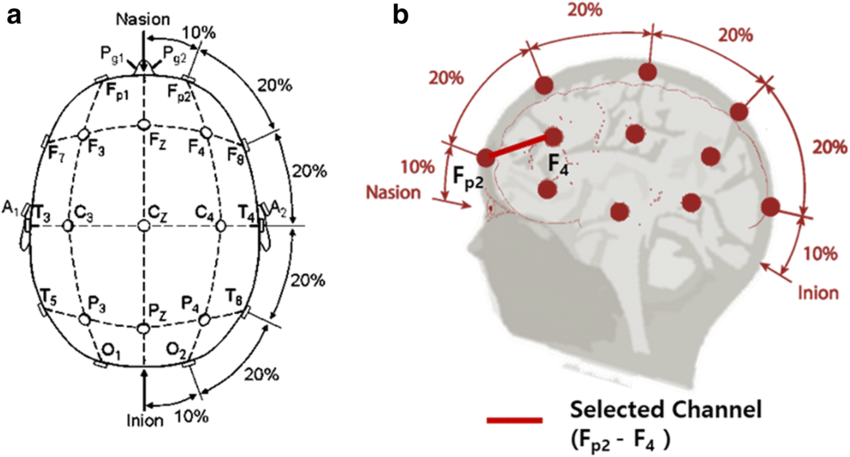

Loading the files with the edf format .


file = "C:\AIE Files\Projects\S3\eeg-during-mental-arithmetic-tasks-1.0.0\Subject00_1.edf"; %Match the edf file path as per the Readme file description.
data = edfread(file)

data = 182×21 timetable
    Record Time        EEGFp1            EEGFp2            EEGF3             EEGF4             EEGF7             EEGF8             EEGT3             EEGT4             EEGC3             EEGC4             EEGT5             EEGT6             EEGP3             EEGP4             EEGO1             EEGO2             EEGFz             EEGCz             EEGPz            EEGA2_A1           ECGECG    
    ___________    ______________    ______________    ______________    ______________    ______________ 

as the frequency of the signal is defined as the number of snapshot it took in a second, from the table we can infer the frequency $f=500$.

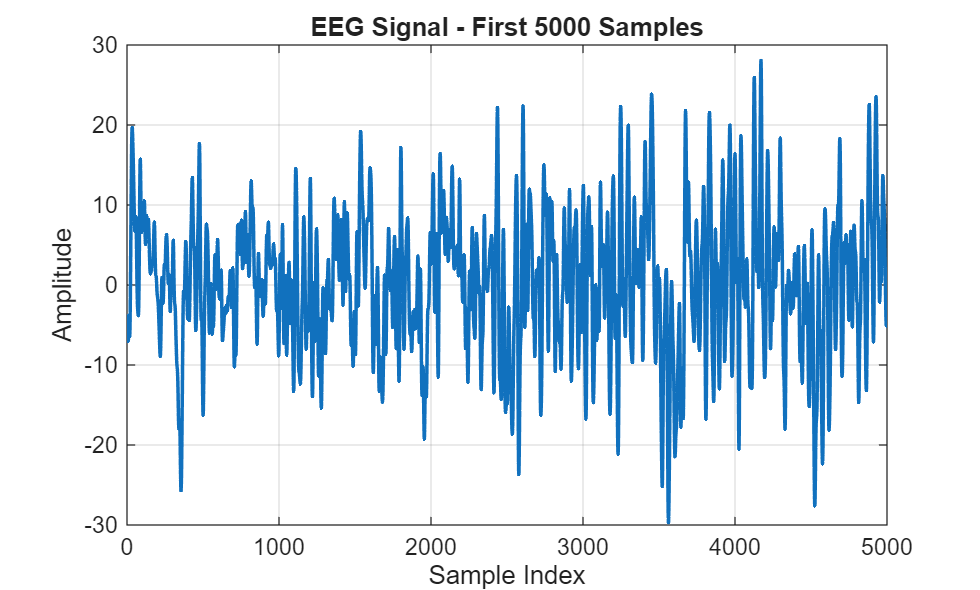

signal = cell2mat(data.EEGFp1);
figure;
plot(signal(1:5000), 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('Amplitude');
title('EEG Signal - First 5000 Samples');
grid on;

%freq = size(signal_1(:,"EEGFp1"))                %  frequency of EEG Signal
%disp(freq);
f = 500;                         


## Soft-Thresholding /Shrinkage:

pushing the values with respect to an threshold values, where the points above threshold are pulled down .Points below the threshold are pushed towards to zero.

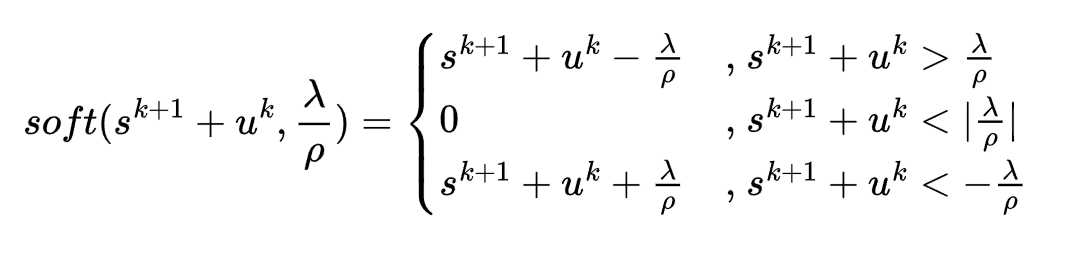

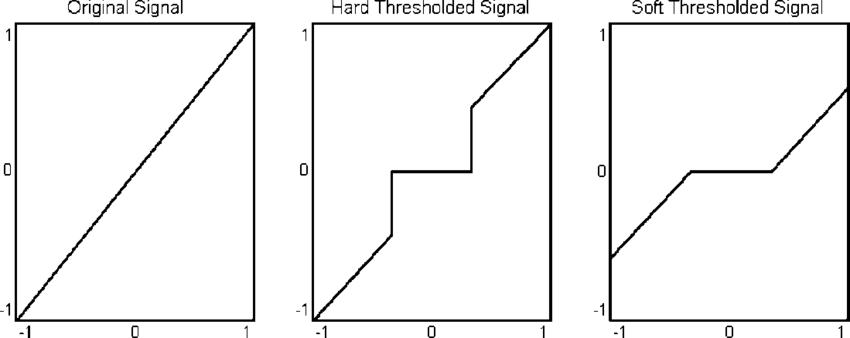

function output = soft_thresholding(x, threshold)
    output = sign(x) .* max(abs(x) - threshold, 0);
end

## Compressed Sensing:

Compressed Sensing (CS) is a signal processing technique that allows us to recover a signal from far fewer samples than what traditional Nyquist-Shannon sampling would require, if the signal is sparse in some basis.If the signal has only a few nonzero coefficients in some transform domain (Fourier, Wavelet, DCT, etc.).

                                                                                                              $f_{\textrm{sampling}} \ge f_{\textrm{signal}}$ , for sampling signals.

Compressed sensing for the Recontruction of the signal is given by,

                                                                                $y=\textrm{Cx}$ where,

                                                                                                       $y\in R^{m\;\;\;\;\;\;\;\;\;} -$Compressed Measurements.

                                                                                                       $x\in R^n \;\;\;\;\;\;\;-$Original signal.

                                                                                                       $C\in R^{m\times n} -$random Gaussion Matrix.

n = 5000;
m = 0.3*n;
fprintf("The of the Original Signal considered is : %d\n",m)

The of the Original Signal considered is : 1500


x = signal(1:n,:)*1e-6;
x_std = std(x);
x_mean = mean(x);
x_norm = (x-x_mean)/x_std;
original = x;
disp(size(x))

        5000           1



rng(0);  % Set random seed for reproducibility
C = randn(m,n) / sqrt(m);  % Generate M×N matrix with standard normal entries
y = C*x;
y_norm = C*x_norm;

## **Sparsity in DCT-II Basis:**

A "Sparsity Basis" (or sparse basis) is a set of basic components (like vectors or functions) that, when used for a specific task, allow for a sparse representation of data.means the original data can be effectively described using a very small number of these basis elements, with most coefficients being zero.

                                                                                     $x=\phi s$where ,

                                                                                                           $\phi \in R^{n\times n} -$DCT coefficient, orthonormal matrix.

                                                                                                            $s-$is sparse vector DCT coefficient, same as the size of 'x'.

 Thus the measurement model becomes,

                                                                   $y=\textrm{Cx}=C\phi s=\textrm{Hs}$ where, 

                                                                                                               $H=C\phi$,$H\in R^{m\times n}$ is the effective sensing matrix.

phi = dct(eye(n));  % by default in matlab dct() gives DCT-II basis matrix
phi = phi/norm(phi) % Since the phi is an orthonormal matrix , from the DCT 

phi =     0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141    0.0141
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200   

Thus the recovery problem becomes , $s$(sparsity) from the 


$$y=\textrm{Hs}$$


LASSO form of Optimization is ,

                                                     
$$\min_{s} \left( \frac{1}{2} \| y - Hs \|_2^2 + \lambda \| s \|_1 \right)\$$


The first term enforces measurement consistency.The second term enforces sparsity.

**____________________________________________________________________________________**

## **ADMM formation:**

Derivation: augmented Lagrangian and ADMM updates

We solve the constrained problem


$$\min_{s,z}\; \frac{1}{2}\|y-Hs\|_2^2 + \lambda\|z\|_1\quad\text{subject to } s=z.$$


Lagrangian (with multiplier $\alpha$):


$$\mathcal{L}(s,z,\alpha)=\frac{1}{2}\|y-Hs\|_2^2 + \lambda\|z\|_1 + \alpha^T(s-z).$$


Augmented Lagrangian penalty $\rho$:


$$\mathcal{L}_\rho(s,z,\alpha)=\frac{1}{2}\|y-Hs\|_2^2 + \lambda\|z\|_1 + \alpha^T(s-z) + \frac{\rho}{2}\|s-z\|_2^2.$$


Considering $u = \frac{\alpha}{\rho}$ we get,

      
$$\rho u^T(s-z)+\frac{\rho}{2}\|s-z\|_2^2 = \frac{\rho}{2}\|s-z+u\|_2^2 - \frac{\rho}{2}\|u\|_2^2.$$


**The constant term **$\frac{\alpha}{\rho}$** does not affect minimization over (s) or (z),**

so we use the simplified form used in the notebook:


$$\tilde{\mathcal{L}}(s,z,u)=\frac{1}{2}\|y-Hs\|_2^2 + \lambda\|z\|_1 + \frac{\rho}{2}\|s-z+u\|_2^2.$$


Below are the ADMM block updates obtained by minimizing $(\tilde{\mathcal{L}})$ alternately.

**____________________________________________________________________________________**

### **s-update (quadratic minimization)**

Solve

         
$$s^{k+1}=\arg\min_s \frac{1}{2}\|y-Hs\|_2^2 + \frac{\rho}{2}\|s-z^k+u^k\|_2^2.$$


Expand and keep only terms depending on $\(s\)$:


$$\tilde{\mathcal{L}}(s,z^k,u^k) = \frac{1}{2}s^T H^T H s - s^T H^T y + \frac{\rho}{2}s^T s - \rho s^T (z^k - u^k) + \text{const}.$$


Collecting quadratic and linear terms gives


$$\tilde{\mathcal{L}}(s,z^k,u^k) = \frac{1}{2} s^T (H^T H + \rho I) s - s^T (H^T y + \rho (z^k - u^k)) + \text{const}.$$


Set gradient to zero: $\frac{\partial \mathcal{L}(s,z^k,u^k)}{\partial s} = 0$


$$(H^T H + \rho I) s - (H^T y + \rho (z^k - u^k)) = 0$$



$$s^{k+1} = (H^T H + \rho I)^{-1}(H^T y + \rho (z^k - u^k)).$$


**____________________________________________________________________________________**

### **z-update (proximal of the l1 norm -> soft threshold)**

Solve

          
$$z^{k+1}=\arg\min_z \lambda\|z\|_1 + \frac{\rho}{2}\|s^{k+1}-z+u^k\|_2^2.$$


Let $v = s^{k+1} + u^k$**, **$\tau = \frac{\lambda}{\rho}$**.**

Shrinkage function with $\lambda \cdot |x|$

            
$$\mathrm{soft}(v,\tau)={sign}(v)\max(|v|-\tau,0).$$



$$z^{k+1}=\mathrm{soft}(s^{k+1}+u^k,\;\lambda/\rho).$$


**____________________________________________________________________________________**

### ** u-update (scaled dual ascent)**

The unscaled dual update is


$$\alpha^{k+1}=\alpha^k + \rho (s^{k+1}-z^{k+1}).$$


Divide by $\rho$ to get the scaled update


$$u^{k+1}=u^k + (s^{k+1}-z^{k+1}).$$


**____________________________________________________________________________________**

### **Final ADMM updates (summary)**


$$s^{k+1} = (H^T H + \rho I)^{-1}(H^T y + \rho (z^k - u^k))$$


 
$$z^{k+1} = \mathrm{soft}(s^{k+1} + u^k,\;\lambda/\rho)$$


 
$$u^{k+1} = u^k + (s^{k+1} - z^{k+1})$$


Declaring the parametes for the ADMM optimization,

rho = 2;              %Controlling parameter
max_iteration = 100;  %Number of iteration for performing the ADMM
lam = 0.1;            %ADMM based parameter 
H = C*phi             %Decalring the sparisity in the DCT equations 

H =    -0.0087   -0.0303    0.0120    0.0172    0.0147   -0.0344    0.0098    0.0022   -0.0244   -0.0230    0.0307   -0.0116   -0.0352   -0.0097   -0.0396   -0.0170    0.0104   -0.0065    0.0405   -0.0620   -0.0083    0.0201    0.0066   -0.0284   -0.0196   -0.0250   -0.0079    0.0247    0.0130   -0.0171    0.0004   -0.0490   -0.0051   -0.0203    0.0720   -0.0004    0.0067    0.0355   -0.0277   -0.0354   -0.0007    0.0101    0.0016   -0.0138   -0.0187   -0.0602    0.0065   -0.0173    0.0067   -0.0148
    0.0133   -0.0049    0.0355    0.0133    0.0176   -0.0146   -0.0567    0.0526    0.0210   -0.0180   -0.0301    0.0378    0.0474   -0.0162   -0.0071    0.0210    0.0103   -0.0348   -0.0361    0.0081    0.0295    0.0238   -0.0497   -0.0044   -0.0400    0.0028   -0.0184    0.0157    0.0217   -0.0230    0.0097    0.0566    0.0115   -0.0188    0.0077   -0.0271   -0.0428    0.0098   -0.0055    0.0340    0.0025    0.0427    0.0038   -0.0094    0.0076    0.0083   -0.0514   -0.0040   -0.0408    0

%ADMM part for the Reconstruction of the EEG Signal
function [s,z,u]=admm(max_iteration,n,H,rho,y,lam)
        s = zeros(n,1);
        z = zeros(n,1);
        u = zeros(n,1);
       K = inv(H'*H+rho*eye(n));
        H_t_y = H'*y
        for i=1:max_iteration
            s = K * (H_t_y+rho*(z-u));
            z = soft_thresholding(s+u,lam/rho);
            u = u+s-z;
        end
end
[s,z,u] = admm(max_iteration,n,H,rho,y_norm,lam);

H_t_y =     2.0013
    4.3481
   -0.8602
    1.2882
    0.8119
    4.2789
   -1.5194
    4.3289
   -0.8457
    7.7709
    1.1053
   -3.1098
   13.0390
   -0.5666
   12.7733


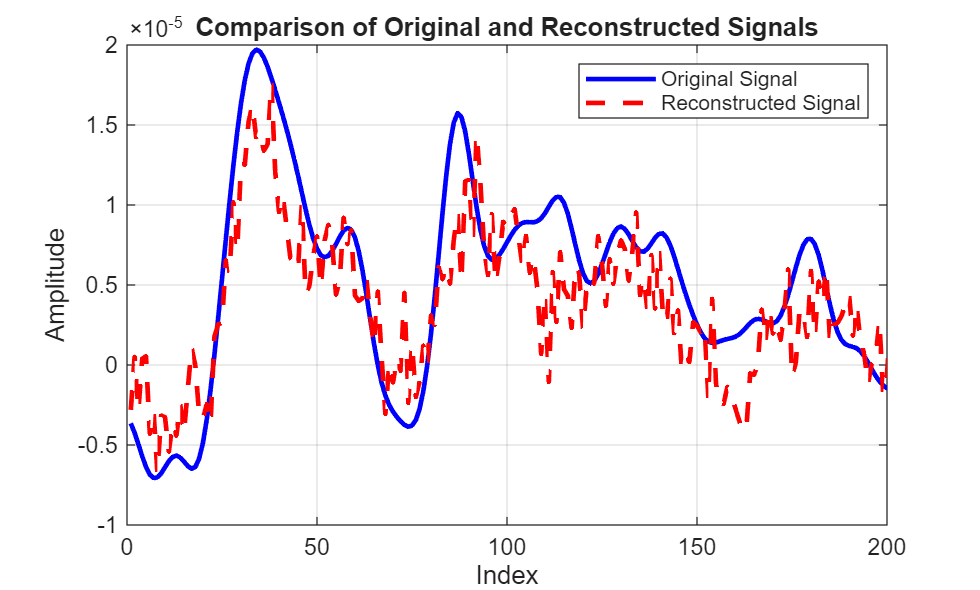

reconstructed_signal_norm = phi * s;
reconstructed_signal = reconstructed_signal_norm*x_std + x_mean;

% Time or index axis
t = 1:length(x);

% Plot both signals
figure;
plot(t, x, 'b-', 'LineWidth', 2); hold on;
plot(t, reconstructed_signal, 'r--', 'LineWidth', 2);
legend('Original Signal', 'Reconstructed Signal');
xlabel('Index');
ylabel('Amplitude');
title('Comparison of Original and Reconstructed Signals');
xlim([0 200]);
grid on;

Computing the RMSE for the Reconstructed signal from the original EEG signal

reconstructed_signal

reconstructed_signal = 1.0e-04 *

   -0.0280
    0.0052
   -0.0285
    0.0039
    0.0055
   -0.0430
   -0.0292
   -0.0672
   -0.0317
   -0.0326
   -0.0541
   -0.0364
   -0.0441
   -0.0245
   -0.0423


rmse = sqrt(sum((original'-reconstructed_signal')'.^2)/length(reconstructed_signal));

Computing the RMSE for the Reconstructed signal from the original EEG signal

fprintf("RMSE:%d",rmse)

RMSE:3.698790e-06

# PART-2:Denoising of the EEG Signals

From the reconstructed signal sample , we will have add an external noise to perform the denoising method with the ADMM update equations.

## Gaussion Noise:

In signal processing theory, Gaussian noise, named after Carl Friedrich Gauss, is a kind of signal noise that has a probability density function (pdf) equal to that of the normal distribution (which is also known as the Gaussian distribution).It acts as small in magnitude and high in density aroud the signal.

                                                                                                          
$$P(x) = \frac{1}{\sqrt{2\pi\sigma^{2}}} \, e^{-\frac{(x - \mu)^{2}}{2\sigma^{2}}}$$


                                                                                                                               Where ,  $\mu-$  mean. 

                                                                                                                                             $\sigma^{2}-$ Standard deviation.

function k_noisy = add_gaussian_noise(k, sigma, alpha, x)
    if nargin < 2
        sigma = 8e-6;
    end
    if nargin < 3
        alpha = 0.5;
    end
    if nargin < 4
        x = k;
    end
    g = randn(length(k), 1) * sigma;
    k_noisy = k + alpha * g;
    figure('Position', [100, 100, 800, 500]);
    plot(x, 'Color', 'blue', 'DisplayName', 'Original Signal');
    hold on;
    plot(g, 'LineStyle', ':', 'Color', 'red', 'DisplayName', 'Gaussian Noise');
    title('Noise effects on EEG Signal');
    xlabel('Samples');
    ylabel('Amplitude');
    legend('show');
    xlim([0 100]);
    grid on;
    hold off;
end

### Laplace noise:

Laplace noise is a type of noise that follows a Laplace distribution, also known as a double exponential distribution. It is characterized by two parameters: the location parameter (μ) and the scale parameter (b).In other words , it is high magnitude and less in density.

                                                                                                      
$$P(x) = \frac{1}{2b} e^{-\frac{\left| x - \mu \right|}{b}}$$


                                                                                                                            Where, $\mu-$  mean

                                                                                                                                         $b-$ Scale Parameter

function k_noisy = add_laplacian_noise(k, b, beta, x)
    if default < 2
        b = 8e-6;
    end
    if default < 3
        beta = 0.5;
    end
    if default < 4
        x = k;
    end
    N = length(k);
    U = rand(N, 1);
    l = -b .* sign(U - 0.5) .* log(1 - 2 * abs(U - 0.5));
    k_noisy = k + beta * l;
    figure('Position', [100, 100, 800, 500]);
    plot(x, 'Color', 'blue', 'DisplayName', 'Original Signal');
    hold on;
    plot(l, 'LineStyle', ':', 'Color', 'green', 'DisplayName', 'Laplacian Noise');
    title('Noise effects on EEG Signal');
    xlabel('Samples');
    ylabel('Amplitude');
    legend('show');
    xlim([0 100]);
    grid on;
    hold off;
end

Considering both the gaussion and laplacia noise,

function k_noisy = add_gaussian_laplacian_noise(k, sigma, b, alpha, beta)
    if nargin < 2
        sigma = 8e-6;
    end
    if nargin < 3
        b = 8e-6;
    end
    if nargin < 4
        alpha = 0.5;
    end
    if nargin < 5
        beta = 0.5;
    end
    N = length(k);
    
    
    g = randn(N, 1) * sigma;
    
    U = rand(N, 1);
    l = -b .* sign(U - 0.5) .* log(1 - 2 * abs(U - 0.5));
   
    k_noisy = k + alpha * g + beta * l;
    
   
end

Now computing the Noise signal , with both gaussion and laplcian Noise

noised_signal = add_gaussian_laplacian_noise(original);

error_signal_Rate = sqrt(mean((original - noised_signal).^2));%Computing how much is varied from the original signal after noise 

fprintf('error is %f\n', error_signal_Rate);

error is 0.000007


fprintf('Size of y: %d\n', length(y));

Size of y: 1500


fprintf('Size of x: %d\n', length(original));

Size of x: 5000


fprintf('Size of Noised Signal: %d\n', length(noised_signal));

Size of Noised Signal: 5000


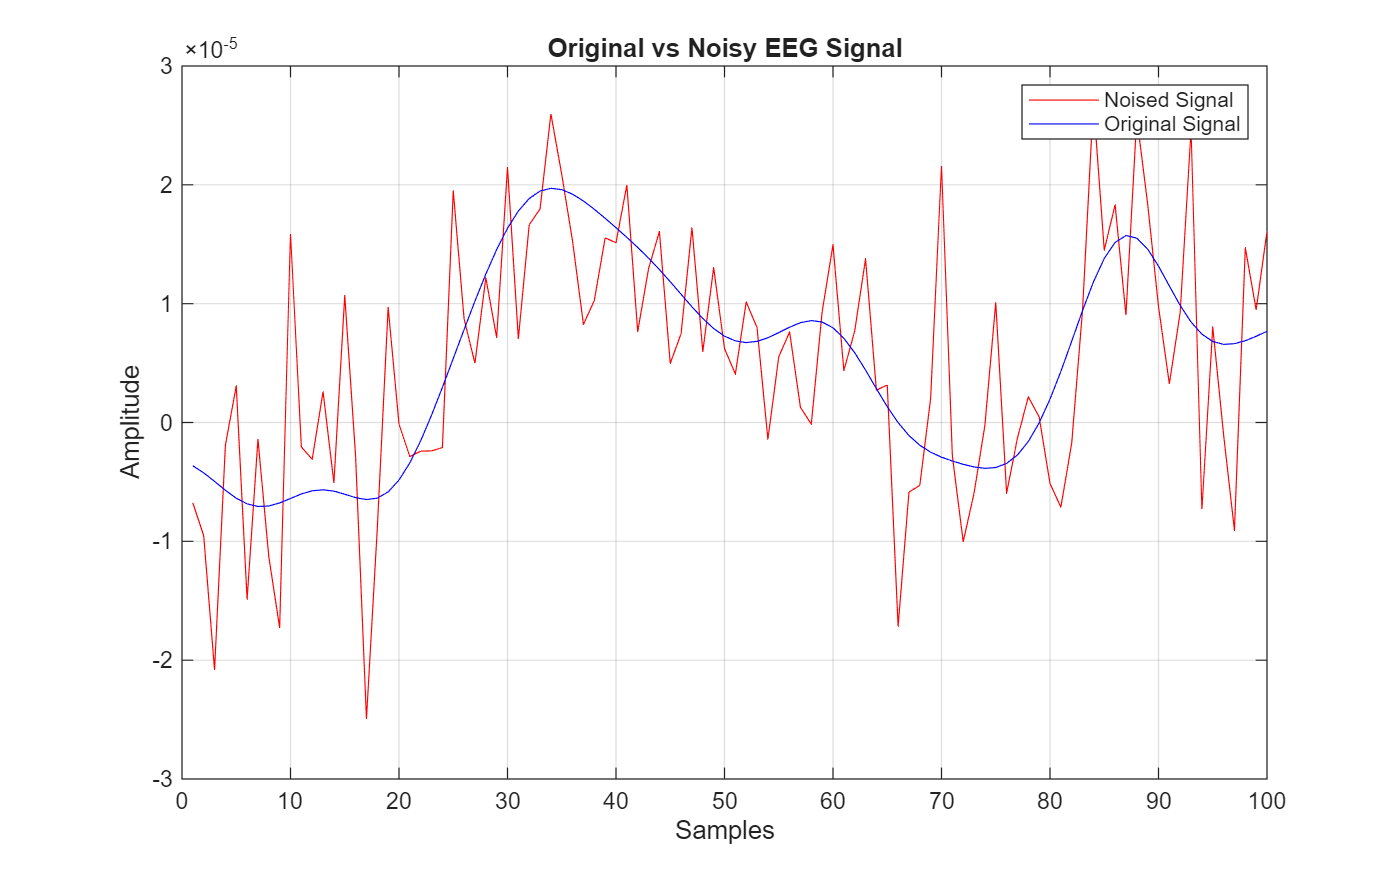


figure('Position', [100, 100, 800, 500]);

plot(noised_signal, 'Color', 'red', 'DisplayName', 'Noised Signal');
hold on;
plot(x, 'Color', 'blue', 'DisplayName', 'Original Signal');

title('Original vs Noisy EEG Signal');
xlabel('Samples');
ylabel('Amplitude');

legend('show');

xlim([0 100]);
grid on;
hold off;

## **Total Variation:**

In simple terms, Total Variation measures how much a signal "jumps" or changes. A signal with a lot of spikes and oscillations has a high Total Variation, while a smooth or piecewise-constant signal has a low Total Variation.

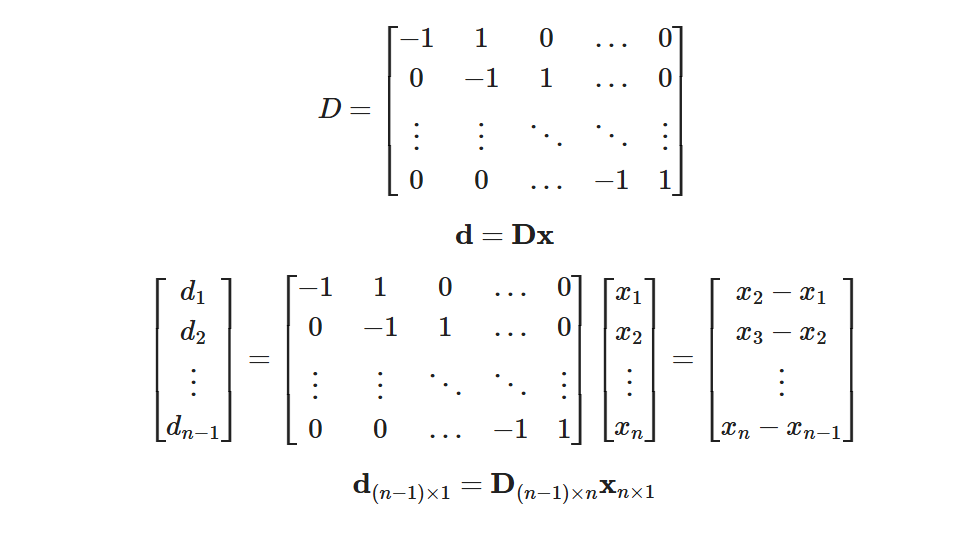

## **Smooth signal condition**


$$\min_{\mathbf{x}} \|\mathbf{d}\|_1 = \min_{\mathbf{x}} \|\mathbf{Dx}\|_1 = \min_{\mathbf{x}} \sum_{i} |x_{i+1} - x_i|$$


**____________________________________________________________________________________**

## ADMM Formulation

**Objective Equation**


$$\underset{x, n_l, z}{\text{minimize}} \quad \frac{1}{2}\|y - x - n_l\|_2^2 + \gamma \|n_l\|_1 + \lambda \|z\|_1 \quad \text{subject to} \quad z = Dx = d$$



$$y\to \textrm{The}\;\textrm{observed}\;,\textrm{noisy}\;\textrm{signal}\left(\textrm{input}\right)$$



$$x\to \textrm{The}\;\textrm{estimated}\;\textrm{clean}\;,\textrm{denoised}\;\textrm{signal}\left(\textrm{output}\right)$$



$$n_l \to \textrm{The}\;\textrm{estimated}\;\textrm{Laplacian}\left(\textrm{spiky}\right)\;\textrm{noisy}\;\textrm{component}$$



$$z\to \textrm{Auxiliary}\;\textrm{variable}\;\textrm{representing}\;\textrm{the}\;{\textrm{signal}}^{\prime } s\;\textrm{gradient}\left(z\approx \textrm{Dx}\right)$$



$$L(x, n_l, z, u) = \frac{1}{2}\|y - x - n_l\|_2^2 + \gamma \|n_l\|_1 + \lambda \|z\|_1 + \alpha^T(Dx - z)$$



$$L_{\rho}(x, n_l, z, u) = \frac{1}{2}\|y - x - n_l\|_2^2 + \gamma \|n_l\|_1 + \lambda \|z\|_1 + \alpha^T(Dx - z) + \frac{\rho}{2}\|Dx - z\|_2^2$$



$$\alpha \to \textrm{The}\;\textrm{dual}\;\textrm{variable}\;\left(\;\textrm{Lagrange}\;\textrm{multiplier}\right)$$



$$\rho \to \textrm{The}\;\textrm{penalty}\;\textrm{parameter}\;\left(a\;\textrm{constant}\right)$$


**____________________________________________________________________________________**

### **Derivation of the `x`-Update**

1. The `x`-update is defined as the argument that minimizes the Augmented Lagrangian:


$$x^{k+1} := \underset{x}{\text{argmin}} \ L_{\rho}(x, n_l^k, z^k, u^k)$$



$$u = \frac{\alpha}{\rho}$$


2. Isolating the terms from the Lagrangian that depend on `x` gives us the subproblem:


$$x^{k+1} = \underset{x}{\text{argmin}} \left( \frac{1}{2}\|y - x - n_l^k\|_2^2 + \frac{\rho}{2}\|Dx - z^k + u^k\|_2^2 \right)$$


3. To find the minimum of this convex function, we set its gradient ($\nabla_x$) to zero:


$$0 = \nabla_x \left( \frac{1}{2}\|(y - n_l^k) - x\|_2^2 + \frac{\rho}{2}\|Dx - (z^k - u^k)\|_2^2 \right)$$


4. Calculating the gradient of each term results in:


$$0 = \left( x - (y - n_l^k) \right) + \rho D^T(Dx - (z^k - u^k))$$


5. Expanding the terms:


$$0 = x - y + n_l^k + \rho D^T Dx - \rho D^T z^k + \rho D^T u^k$$


6. Now, we rearrange the equation to solve for `x` by moving all non-`x` terms to the right side:


$$x + \rho D^T Dx = y - n_l^k + \rho D^T z^k - \rho D^T u^k$$


7. Finally, factoring out `x` on the left and `ρDᵀ` on the right yields the final result:


$$(I + \rho D^T D)x = y - n_l^k + \rho D^T(z^k - u^k)$$



$$x^{k+1} = (I + \rho D^T D)^{-1} (y - n_l^k + \rho D^T(z^k - u^k))$$


**____________________________________________________________________________________**

### **The **$n_l$**-update is defined as:**


$$n_l^{k+1} := \underset{n_l}{\text{argmin}} \ L_{\rho}(x^{k+1}, n_l, z^k, u^k)$$


Isolating the terms dependent on $n_l$ from the Lagrangian:


$$n_l^{k+1} = \underset{n_l}{\text{argmin}} \left( \frac{1}{2}\|y - x^{k+1} - n_l\|_2^2 + \gamma \|n_l\|_1 \right)$$


Let the residual signal be $v = y - x^{k+1}$. The problem becomes:


$$n_l^{k+1} = \underset{n_l}{\text{argmin}} \left( \frac{1}{2}\|v - n_l\|_2^2 + \gamma \|n_l\|_1 \right)$$



$$\mathrm{soft}(v,\tau)=\ {sign}(v)\max(|v|-\gamma,0)$$



$$n_l^{k+1} = \mathrm{soft}(y - x^{k+1};\gamma)$$


**____________________________________________________________________________________**

### **Simplified z-update Derivation**

**The **$z$**-update is defined as:**

                                               
$$z^{k+1} = \underset{z}{\text{argmin}} \ L_{\rho}(x^{k+1}, n_l^{k+1}, z, u^k)$$


From the augmented Lagrangian, only terms involving $z$ matter for minimization:


$$z^{k+1} = \underset{z}{\text{argmin}} \left( \lambda \|z\|_1 + u^{k^T}(Dx^{k+1} - z) + \frac{\rho}{2}\|Dx^{k+1} - z\|_2^2 \right)$$


**Let **$v = Dx^{k+1} + u^k$**. **The problem becomes**:**


$$z^{k+1} = \underset{z}{\text{argmin}} \left( \lambda \|z\|_1 + \frac{\rho}{2}\|z - v\|_2^2 \right)$$


This optimization problem has a closed-form solution using the **soft-thresholding operator**, which is the proximal operator of the $\ell_1$ norm:


$$z^{k+1} = \mathrm{soft}(v, \lambda/\rho) = \mathrm{soft}(Dx^{k+1} + u^k,\;\lambda/\rho)$$


The **shrinkage function** (soft-thresholding) is defined element-wise as:


$$\mathrm{soft}(v_i, \tau) = {sign}(v_i) \max(|v_i| - \tau, 0)$$


where $\tau = \frac{\lambda}{\rho}$ is the threshold parameter.

**Why is it called a shrinkage function?**

- It "shrinks" values toward zero by subtracting the threshold $\tau$

- Values with $|v_i| < \tau$ become exactly zero (promotes sparsity)

- Values with $|v_i| > \tau$ are reduced in magnitude by $\tau$

- The sign is preserved, so the function operates symmetrically around zero

This shrinkage property makes soft-thresholding ideal for enforcing sparsity through the $\ell_1$ penalty term $\lambda \|z\|_1$.

**____________________________________________________________________________________**

### ** u-update (scaled dual ascent):**

The dual variable update step in ADMM keeps track of the constraint violation between $Dx$ and $z$. 

The unscaled dual update is:


$$\alpha^{k+1} = \alpha^k + \rho (Dx^{k+1} - z^{k+1})$$


Since we use the scaled form with $u = \frac{\alpha}{\rho}$, dividing both sides by $\rho$ gives the scaled update:


$$u^{k+1} = u^k + (Dx^{k+1} - z^{k+1})$$


This update accumulates the residual (difference between $Dx$ and $z$) over iterations, which helps enforce the equality constraint $z = Dx$ in the augmented Lagrangian formulation.

**____________________________________________________________________________________**

**Update equations (Summary):**


$$x^{k+1} = (I + \rho D^T D)^{-1} (y - n_l^k + \rho D^T(z^k - u^k))$$



$$n_l^{k+1} = \mathrm{soft}(y - x^{k+1};\gamma)$$



$$z^{k+1} = \mathrm{soft}(v, \lambda/\rho) = \mathrm{soft}(Dx^{k+1} + u^k,\,\lambda/\rho)$$



$$u^{k+1} = u^k + (Dx^{k+1} - z^{k+1})$$


function x = denoise_mixed_admm_matrix_form(y, lam, gamma, rho, max_iter, tol)
    if nargin < 4
        rho = 0.014;
    end
    if nargin < 5
        max_iter = 350;
    end
    if nargin < 6
        tol = 1e-6;
    end

    n = length(y);

    D = eye(n) - diag(ones(n-1, 1), 1);
    D = D(1:n-1, :);
    DT = D';

    I = eye(n);
    M = I + rho * DT * D;
    M_inv = inv(M);

    x = y;
    n_l = zeros(n, 1);
    z = zeros(n - 1, 1);
    u = zeros(n - 1, 1);

    for k = 1:max_iter
        x_old = x;

        rhs_x = y - n_l + rho * DT * (z - u);

        x = M_inv * rhs_x;

        n_l = soft_thresholding(y - x, gamma);

        Dx = D * x;
        z = soft_thresholding(Dx + u, lam / rho);

        u = u + (Dx - z);

        rel_change = norm(x - x_old) / (norm(x_old) + 1e-9);
        if rel_change < tol
            break;
        end
    end
    fprintf('Converged after %d iterations.\n', k);
end

figure('Position', [100, 100, 800, 500]);

%denoisng the signal using the ADMM operator
denoised_signal = denoise_mixed_admm_matrix_form(noised_signal, 0.0001, 0.1);

Converged after 350 iterations.


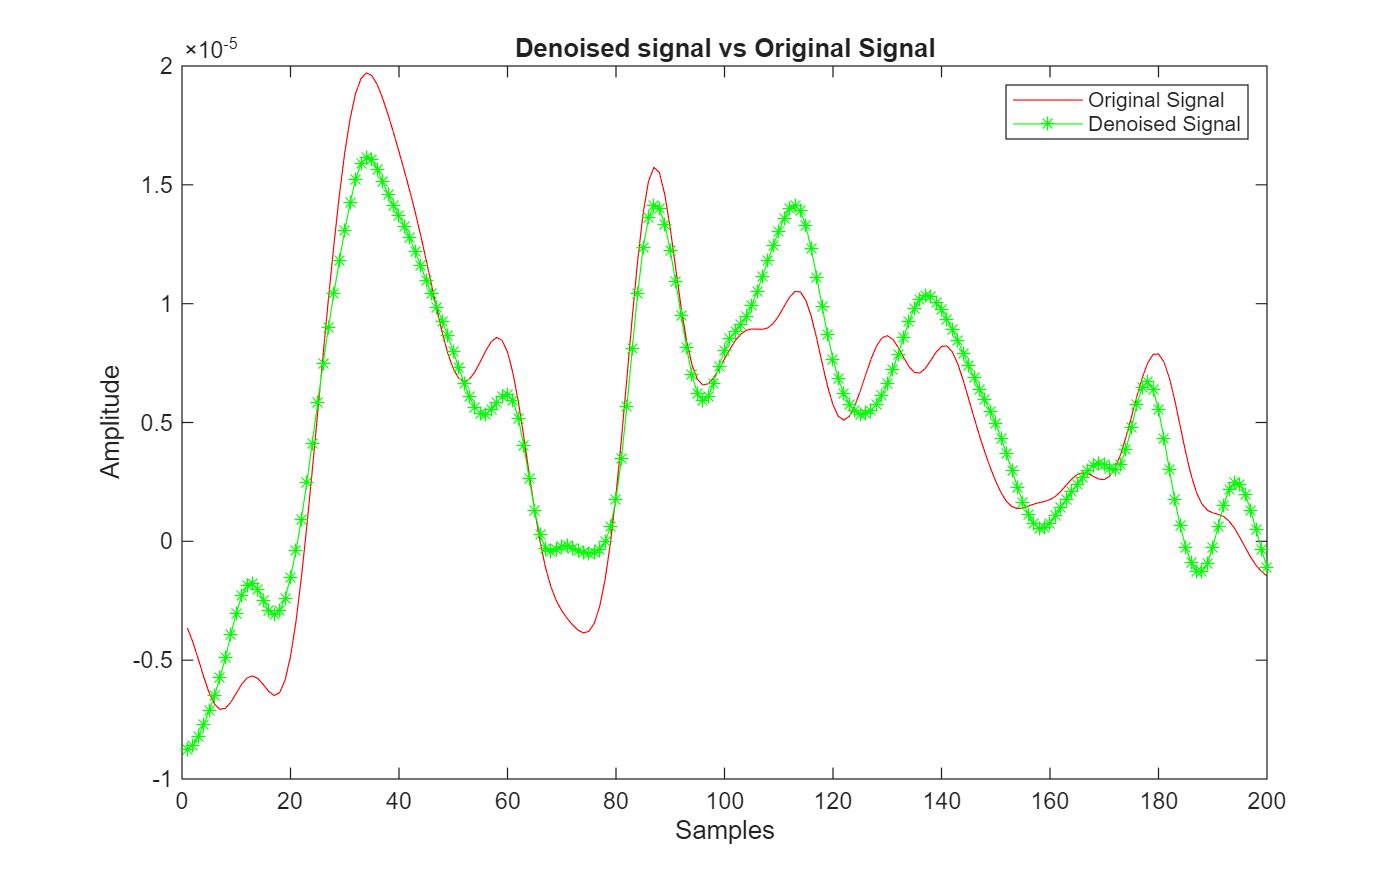


plot(original, 'Color', 'red', 'DisplayName', 'Original Signal');
hold on;
plot(denoised_signal, 'Color', 'green', 'Marker', '*', 'LineStyle', '-', 'DisplayName', 'Denoised Signal');

title('Denoised signal vs Original Signal');
xlabel('Samples');
ylabel('Amplitude');

legend('show');
xlim([0 200]);
hold off;

rmse_denoising = sqrt(sum((original - denoised_signal).^2) / length(original));
fprintf("RMSE for the DENOISED SIGNAL: %.6f\n", rmse_denoising);

RMSE for the DENOISED SIGNAL: 0.000002


## Frequency Response Comparison Plot:

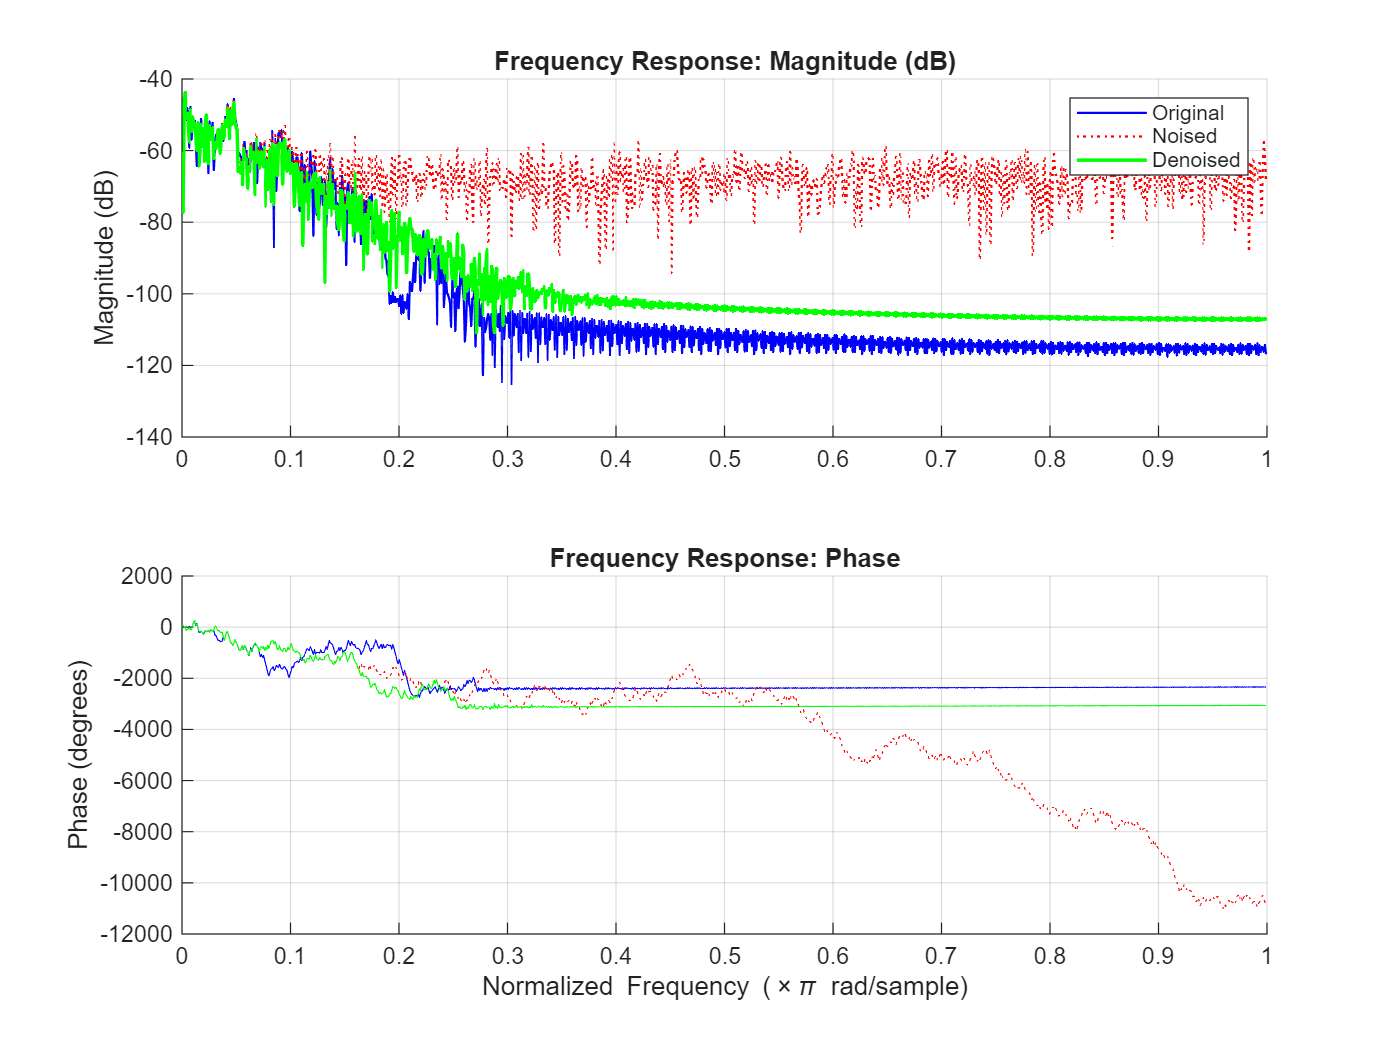

n_fft = 1024;
fs = 500; 

% Compute Responses for all three signals
[H_orig, W] = freqz(original, 1, n_fft, fs); 
[H_noise, ~] = freqz(noised_signal, 1, n_fft, fs);
[H_denoise, ~] = freqz(denoised_signal, 1, n_fft, fs);

figure('Name', 'Spectral Comparison', 'Position', [150, 150, 800, 600]);

% Magnitude Comparison Plot
subplot(2,1,1);
hold on;
plot(W/(fs/2), 20*log10(abs(H_orig)), 'b', 'LineWidth', 1);       % Original
plot(W/(fs/2), 20*log10(abs(H_noise)), 'r:', 'LineWidth', 1);    % Noised (dotted)
plot(W/(fs/2), 20*log10(abs(H_denoise)), 'g', 'LineWidth', 1.5); % Denoised
title('Frequency Response: Magnitude (dB)');
ylabel('Magnitude (dB)');
legend('Original', 'Noised', 'Denoised');
grid on;

% Phase Comparison Plot
subplot(2,1,2);
hold on;
plot(W/(fs/2), unwrap(angle(H_orig))*(180/pi), 'b');
plot(W/(fs/2), unwrap(angle(H_noise))*(180/pi), 'r:');
plot(W/(fs/2), unwrap(angle(H_denoise))*(180/pi), 'g');
title('Frequency Response: Phase');
ylabel('Phase (degrees)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
grid on;
hold off;